close all;clc;clear;
handle  = OCTFileOpen('Default_0193_Mode2D.oct');
disp( OCTFileGetProperty(handle, 'AcquisitionMode') );

Mode2D


disp( OCTFileGetProperty(handle, 'RefractiveIndex') );

1.000000


disp( OCTFileGetProperty(handle, 'Comment') );
disp( OCTFileGetProperty(handle, 'Study') );

Default


disp( OCTFileGetProperty(handle, 'ExperimentNumber') );

193


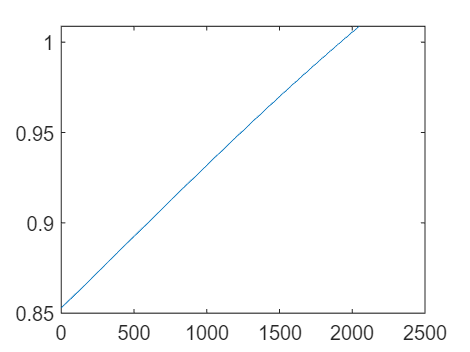

%-----------------------------------------------------------
%reading spectral raw data
NrRawData = OCTFileGetNrRawData(handle);
[RawData, Spectrum] = OCTFileGetRawData(handle, 0);
% plot(1:2048,RawData(:,1));

load('Wavelength.mat','Wavelength'); 
plot(1:2048,Wavelength);

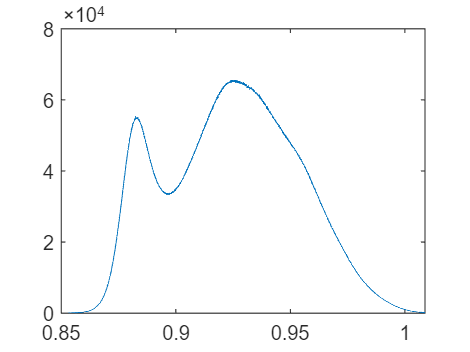

plot(Wavelength,Spectrum);

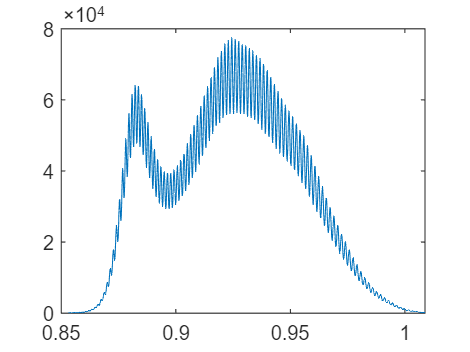

plot(Wavelength,RawData(:,1));

%光谱整形

